## Construct 3-phase sampled signal

You could either create a synthetic signal or read a sampled signal from a file:

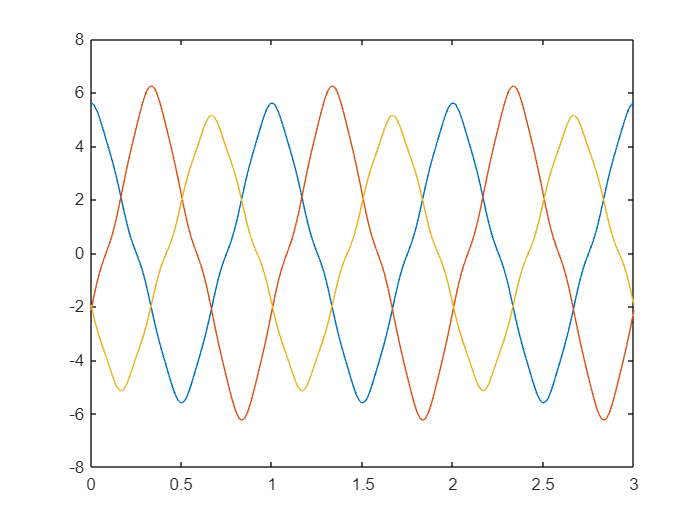

clearvars;

% Fundamental frequency
f = 1;
w = 2 * pi * f;

% Sampling rate in samples/cycle
fs = 1000;

% Signal cycles count
nc = 3;

% Sampled time
t = linspace(0, nc / f, fs * nc + 1);

% Signal sample count
n = length(t);

% Harmonic Signal components
angles = [w * t; w * t - 2 * pi / 3; w * t + 2 * pi / 3];

m = [
    5, 0.5, 0.1; 
    5.5, 0.65, 0.09; 
    4.6, 0.42, 0.12
];

a = m(1,1) * cos(angles(1,:)) + m(1,2) * cos(3 * angles(1,:)) + m(1,3) * cos(7 * angles(1,:));
b = m(2,1) * cos(angles(2,:)) + m(2,2) * cos(3 * angles(2,:)) + m(2,3) * cos(7 * angles(2,:));
c = m(3,1) * cos(angles(3,:)) + m(3,2) * cos(3 * angles(3,:)) + m(3,3) * cos(7 * angles(3,:));

signal = [a; b; c];

plot(t,a);
hold on;
plot(t,b);
plot(t,c);
hold off;

## Define the first arc-length derivative:

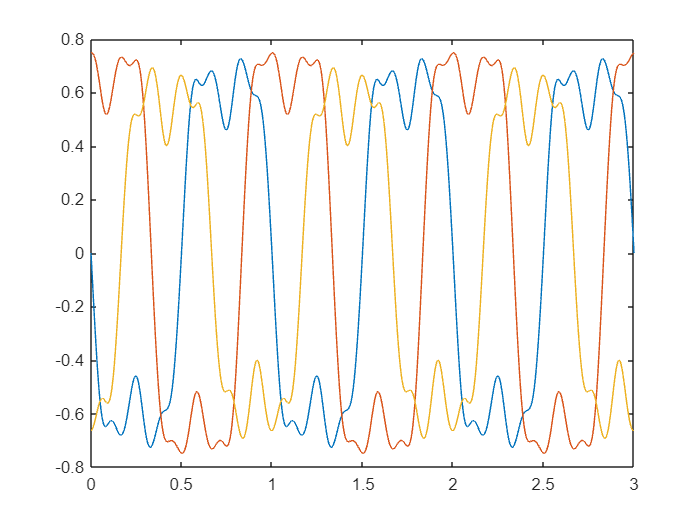

aDt = -w * m(1,1) * sin(angles(1,:)) - 3 * w * m(1,2) * sin(3 * angles(1,:)) - 7 * w * m(1,3) * sin(7 * angles(1,:));
bDt = -w * m(2,1) * sin(angles(2,:)) - 3 * w * m(2,2) * sin(3 * angles(2,:)) - 7 * w * m(2,3) * sin(7 * angles(2,:));
cDt = -w * m(3,1) * sin(angles(3,:)) - 3 * w * m(3,2) * sin(3 * angles(3,:)) - 7 * w * m(3,3) * sin(7 * angles(3,:));

signalDt = [aDt; bDt; cDt];
sDt = sqrt(sum(signalDt .* signalDt, 1));
signalDs = signalDt ./ repmat(sDt, [3, 1]);

plot(t,signalDs(1,:));
hold on;
plot(t,signalDs(2,:));
plot(t,signalDs(3,:));
hold off;

## Local Optimization Algorithm

majorThetaSamples = zeros(1,n);
majorLengthSamples = zeros(1,n);
minorLengthSamples = zeros(1,n);
shapeIndexSamples = zeros(1,n);

% take a number of samples equal to 1/4 of a cycle
k = round(fs/4); 

nk = (k - 1) / 2;

for s = 1:(n - k)
    signalPart = signal(:, s:(s + k - 1));
    signalDsPart = signalDs(:, s:(s + k - 1));

    % Use Clarke transform to rotate signal to align (1,1,1) with z-axis
    C = sqrt(2/3) * [
        1,          -1/2,       -1/2;
        0,          sqrt(3)/2,  -sqrt(3)/2;
        1/sqrt(2),  1/sqrt(2),  1/sqrt(2)
    ];
    
    signalPart = C * signalPart;    
    p1 = signalPart(1, :);
    p2 = signalPart(2, :);
    p3 = signalPart(3, :);

    % plot(p1(1:k)); hold on; plot(p2(1:k)); plot(p3(1:k)); hold off;

    % Now we can take first 2 projected signal components and try finding the best-fit ellipse
    points = [p1, -p1; p2, -p2];
    
    % We could down-sample the signal here, we don't practically need all these samples
    % points = points(:, 1:10:k);
        
    % Plot points
    % plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");

    % Fit ellipse to points
    [centerX, centerY, majorTheta, majorLength, minorLength] = fitEllipseGAC(points);
    
    majorThetaSamples(s) = majorTheta;
    majorLengthSamples(s) = majorLength;
    minorLengthSamples(s) = minorLength;
    shapeIndexSamples(s) = minorLength / majorLength;

    % Plot points and ellipse
    % ellipsePoints = getEllipsePoints(majorLength, minorLength, majorTheta, centerX, centerY, 361);
    %
    % plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");
    % hold on;
    % plot(ellipsePoints(1,:), ellipsePoints(2,:), "LineStyle","-");
    % hold off;
end

mean(majorThetaSamples) * 180 / pi

ans = -43.3177

mean(majorLengthSamples)

ans = 6.0480

mean(minorLengthSamples)

ans = 5.2636

mean(shapeIndexSamples)

ans = 0.7982

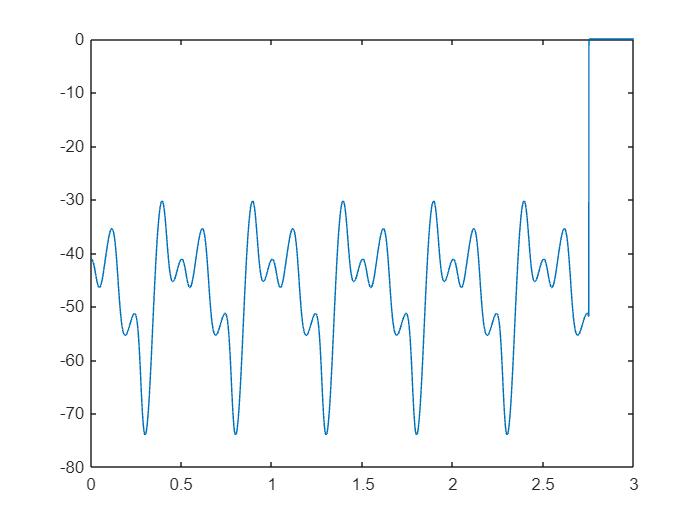


plot(t,majorThetaSamples*180/pi);

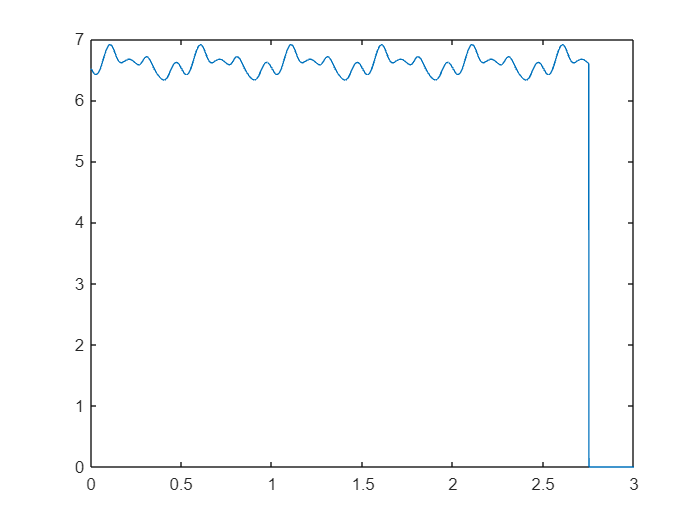

plot(t,majorLengthSamples);

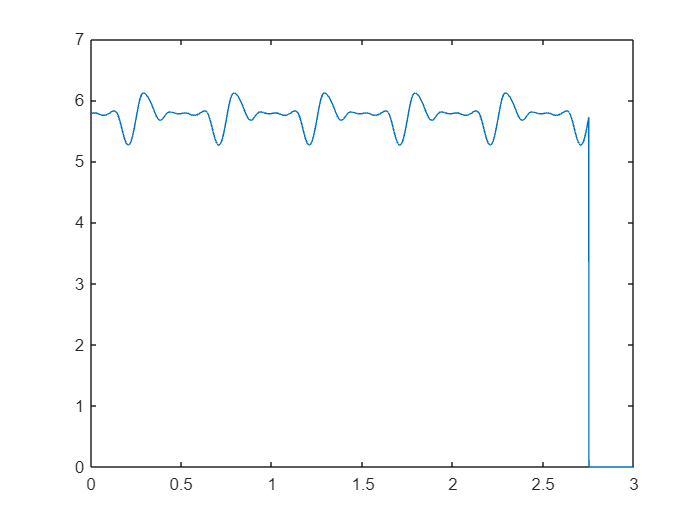

plot(t,minorLengthSamples);

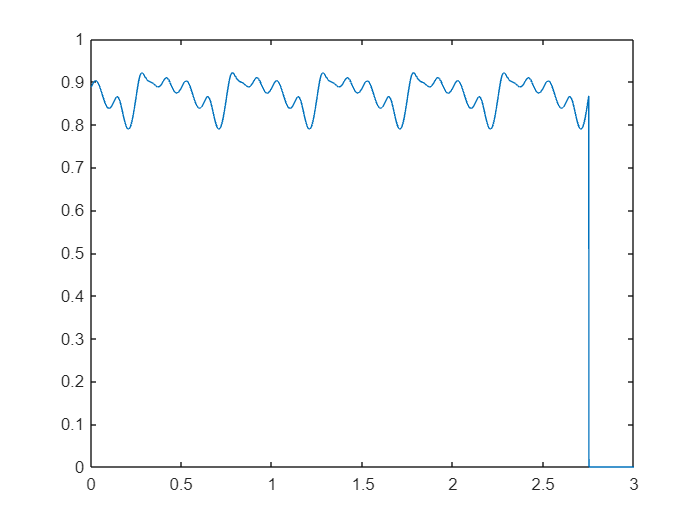

plot(t,shapeIndexSamples);